% Import Telemetry Data
clear; clc;
data = ImportTelemetry("sat_realtime_telemetry.csv");

## Voltage Data

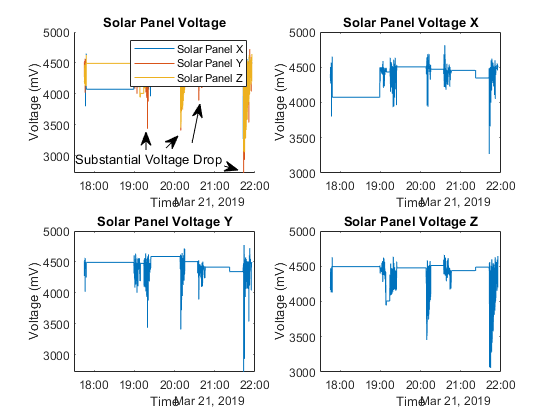

% Plotting solar panel data together, then separately.

subplot(2,2,1);
    hold on;
    plot(data.SatelliteDateTimeUTC, data.SolarPanelVoltageXMV);
    plot(data.SatelliteDateTimeUTC, data.SolarPanelVoltageYMV);
    plot(data.SatelliteDateTimeUTC, data.SolarPanelVoltageZMV);
    
    title('Solar Panel Voltage');
    xlabel('Time');
    ylabel('Voltage (mV)');
    legend({'Solar Panel X','Solar Panel Y','Solar Panel Z'});
    legend({'Solar Panel X','Solar Panel Y','Solar Panel Z'});
hold off;

subplot(2,2,2);
    plot(data.SatelliteDateTimeUTC, data.SolarPanelVoltageXMV);
    title('Solar Panel Voltage X');
    xlabel('Time');
    ylabel('Voltage (mV)');

subplot(2,2,3);
    plot(data.SatelliteDateTimeUTC, data.SolarPanelVoltageYMV);
    title('Solar Panel Voltage Y');
    xlabel('Time');
    ylabel('Voltage (mV)');

subplot(2,2,4);
    plot(data.SatelliteDateTimeUTC, data.SolarPanelVoltageZMV);
    title('Solar Panel Voltage Z');
    xlabel('Time');
    ylabel('Voltage (mV)');

annotation('arrow',[0.4 0.425],[0.6048 0.5952]);
annotation('arrow',[0.3429 0.3571],[0.6595 0.7524]);
annotation('arrow',[0.2964 0.3179],[0.6476 0.6762]);
annotation('textarrow',[0.2607 0.2607],[0.6429 0.6857],'String','Substantial Voltage Drop');

The solar panels are all dropping in voltage around the same time. Likely interference from other spacecraft and/or orbital position in relation to the sun.

Voltage Drops at approximately: 19:08, 19:20, 20:09, 20:36, and 21:43.

## Battery and General System Current Data

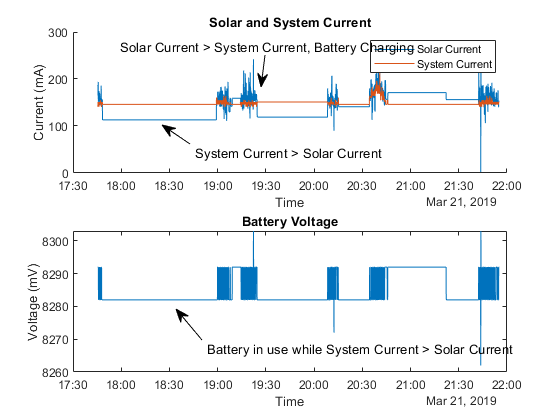

close all hidden;

% Plotting current use and supply
subplot(2, 1, 1);
    hold on;
    plot(data.SatelliteDateTimeUTC, data.TotalPhotoCurrentMA);
    plot(data.SatelliteDateTimeUTC, data.TotalSystemCurrentMA);
    title('Solar and System Current');
    xlabel('Time');
    ylabel('Current (mA)');
    legend({'Solar Current','System Current'});
    annotation('textarrow',[0.3393 0.2893],[0.6571 0.7024],'String','System Current > Solar Current');
    annotation('textarrow',[0.4732 0.4661],[0.869 0.7929],'String','Solar Current > System Current, Battery Charging');
    hold off;

% Plotting battery status
subplot(2, 1, 2);
    plot(data.SatelliteDateTimeUTC, data.BatteryVoltageMV);
    title('Battery Voltage');
    xlabel('Time');
    ylabel('Voltage (mV)');
    annotation('textarrow',[0.3607 0.3143],[0.1905 0.2643],'String','Battery in use while System Current > Solar Current');

The goal is definitely for the photovoltaic current to stay above the system current, as to pull power from the battery as little as possible. In this case, we see that we are unable to sustain the system current with our solar panels for the majority of the time, relying on supplementary power from the battery which causes a clear voltage drop while the battery is supplementing the system current. However, when solar availability increases (increased current and voltage), the solar current supplies more than enough power to power the system as well as charge the battery, shown by the upticks in battery voltage where no power is being drawn from the battery and the battery is assumingly being charged as well.

## Internal Electronics Data

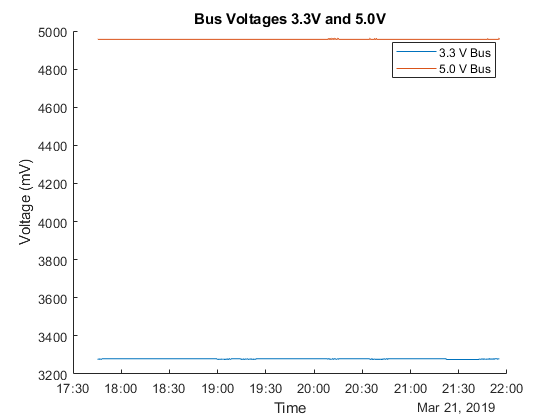

close all hidden;

% Voltage First
hold on;
plot(data.SatelliteDateTimeUTC, data.BusVoltageMV);
plot(data.SatelliteDateTimeUTC, data.BusVoltageMV1);
title('Bus Voltages 3.3V and 5.0V');
xlabel('Time');
ylabel('Voltage (mV)');
legend({'3.3 V Bus','5.0 V Bus'})
hold off;

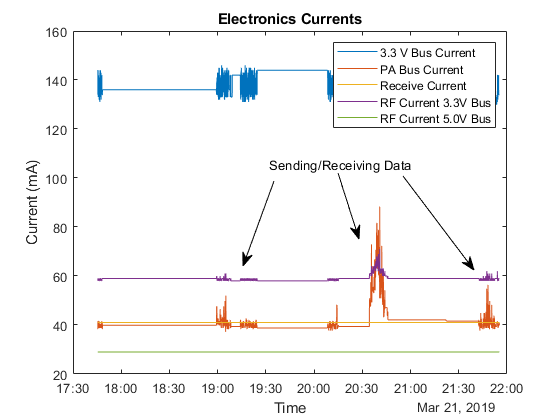


% Electronic Current

plot(data.SatelliteDateTimeUTC, data.BusCurrentMA);
hold on;
plot(data.SatelliteDateTimeUTC, data.PABusCurrentMA);
plot(data.SatelliteDateTimeUTC, data.ReceiveCurrentMA);
plot(data.SatelliteDateTimeUTC, data.RFCurrent33VBusMA);
plot(data.SatelliteDateTimeUTC, data.RFCurrent50VBusMA);
title('Electronics Currents');
xlabel('Time');
ylabel('Current (mA)');
legend({'3.3 V Bus Current','PA Bus Current', 'Receive Current', 'RF Current 3.3V Bus', 'RF Current 5.0V Bus'})
hold off;

annotation('arrow',[0.4893 0.4339],[0.569 0.3667]);
annotation('arrow',[0.7196 0.8464],[0.581 0.3571]);
annotation('textarrow',[0.6036 0.6411],[0.5881 0.431],'String','Sending/Receiving Data');

Bus voltages are within regular margins. Spikes in RF Current are likely due to sending and/or receiving data from Earth. Stable current indicates RF Receiver is idle. RF seems to be working around the same time of solar interference from the solar panels. Likely sending data regarding interference from other spacecraft or positioning.

## Temperature and Sun Data

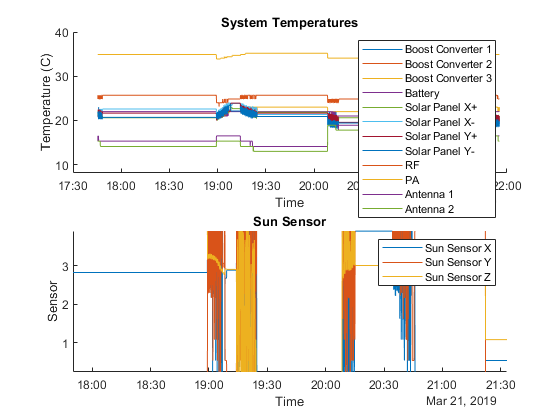

close all hidden;

% Plotting Temperatures of Systems
subplot(2, 1, 1);
hold on;
plot(data.SatelliteDateTimeUTC, data.BoostConverterTemp1C);
plot(data.SatelliteDateTimeUTC, data.BoostConverterTemp2C);
plot(data.SatelliteDateTimeUTC, data.BoostConverterTemp3C);
plot(data.SatelliteDateTimeUTC, data.BatteryTempC);
plot(data.SatelliteDateTimeUTC, data.SolarPanelTempXC);
plot(data.SatelliteDateTimeUTC, data.SolarPanelTempXC1);
plot(data.SatelliteDateTimeUTC, data.SolarPanelTempYC);
plot(data.SatelliteDateTimeUTC, data.SolarPanelTempYC1);
plot(data.SatelliteDateTimeUTC, data.RFTemperatureC);
plot(data.SatelliteDateTimeUTC, data.PADeviceTemperatureC);
plot(data.SatelliteDateTimeUTC, data.AntennaTemp0C);
plot(data.SatelliteDateTimeUTC, data.AntennaTemp1C);
legend({'Boost Converter 1','Boost Converter 2', 'Boost Converter 3', 'Battery','Solar Panel X+','Solar Panel X-','Solar Panel Y+','Solar Panel Y-','RF','PA','Antenna 1','Antenna 2'})
title('System Temperatures')
xlabel('Time')
ylabel('Temperature (C)')
hold off;

subplot(2, 1, 2);
hold on;
plot(data.SatelliteDateTimeUTC, data.SunSensorX);
plot(data.SatelliteDateTimeUTC, data.SunSensorY);
plot(data.SatelliteDateTimeUTC, data.SunSensorZ);
title('Sun Sensor')
xlabel('Time')
ylabel('Sensor')
legend({'Sun Sensor X', 'Sun Sensor Y', 'Sun Sensor Z'})
hold off;

The temperatures are proportional to the current of its systems, when the systems are working, the temperature increases and when it is not working , it decreases. This ends up being related to when there is solar light contact with the solar panels. Something strange is happening with the sun sensors, the sunlight detected is changing very rapidly and significantly. Most likely due to interference from other space objects including spacecrafts, satellites, and asteroids. Potentially spinning, however unlikely due to power required to induce and control this spinning, and the relatively small power output of this spacecraft.